## Load Test result

dataset = Baseline_Result

dataset = Simulink.SimulationData.Dataset 'Baseline_Result' with 2 elements

                         Name        BlockPath                             
                         __________  _____________________________________ 
    1  [1x1 Signal]      PWMRequest  motor_control_new_trial_baseline/Out1
    2  [1x1 Signal]      Counter     motor_control_new_trial_baseline/Out2

  - Use braces { } to access, modify, or add elements using index.


## Preview Input - PWM

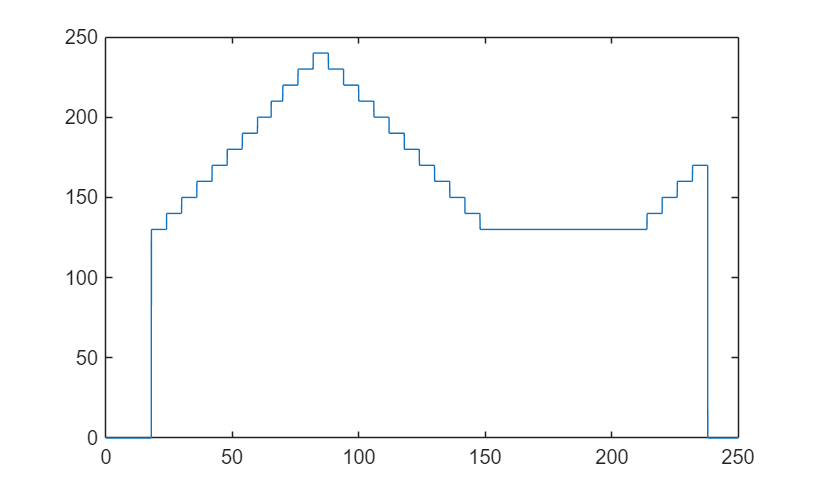

PWMRequest = dataset{1}.Values.Data;
PWMRequest_time = dataset{1}.Values.Time;
PWMRequest = double(PWMRequest);
plot(PWMRequest_time,PWMRequest)

## Preview Output - RPM

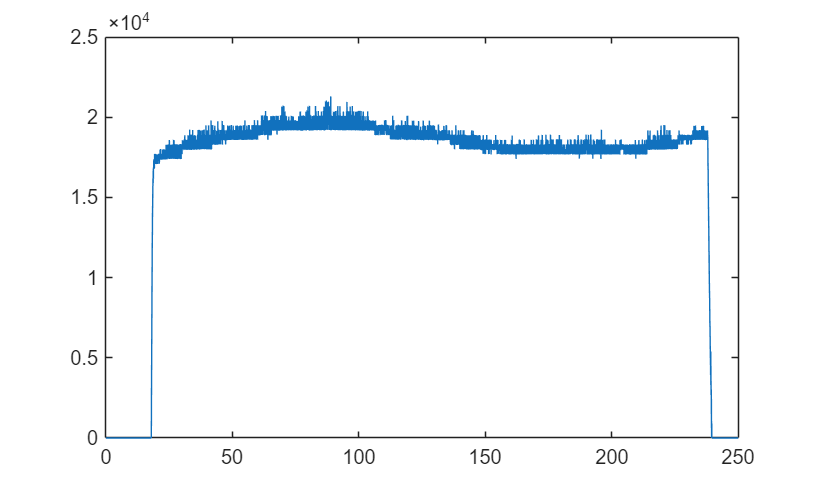

RPMResult = dataset{2}.Values.Data(:);
RPMResult_time = dataset{2}.Values.Time;
plot(RPMResult_time,RPMResult)

## Prepare data - Convert to double for processing

PWMRequest = double(PWMRequest);
RPMResult = double(RPMResult);

## Preprocessing - Clean outlier - Moving median

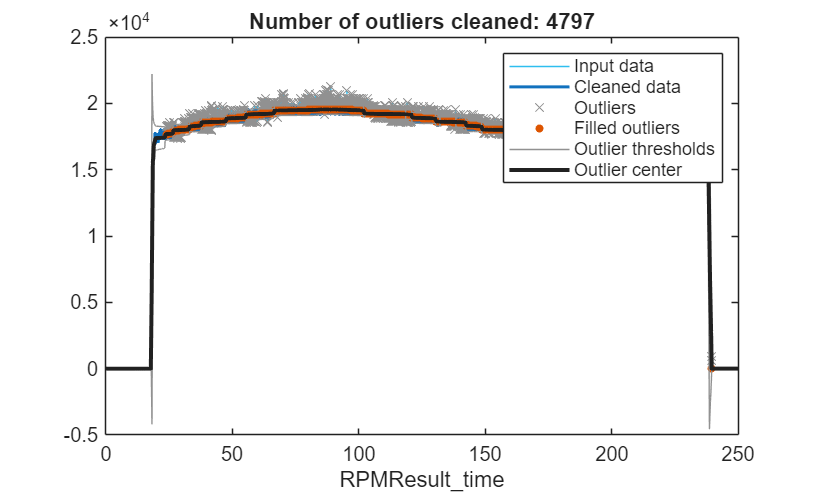

% Fill outliers
[RPMResult_Clean,outlierIndices,lo,hi,center] = filloutliers(RPMResult,"center", ...
    "movmedian",16,ThresholdFactor=1,SamplePoints=RPMResult_time);

% Display results
figure
plot(RPMResult_time,RPMResult,SeriesIndex=6,DisplayName="Input data")
hold on
plot(RPMResult_time,RPMResult_Clean,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Cleaned data")

% Plot outliers
plot(RPMResult_time(outlierIndices),RPMResult(outlierIndices),"x", ...
    Color=[145 145 145]/255,DisplayName="Outliers")

% Plot filled outliers
plot(RPMResult_time(outlierIndices),RPMResult_Clean(outlierIndices),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled outliers")

% Plot outlier thresholds
plot([RPMResult_time(:); missing; RPMResult_time(:)],[hi(:); missing; lo(:)], ...
    Color=[145 145 145]/255,DisplayName="Outlier thresholds")

% Plot outlier center
plot(RPMResult_time,center,SeriesIndex="none",LineWidth=2, ...
    DisplayName="Outlier center")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
xlabel("RPMResult_time",Interpreter="none")

clear lo hi center

## Preview Data after cleaning outlier

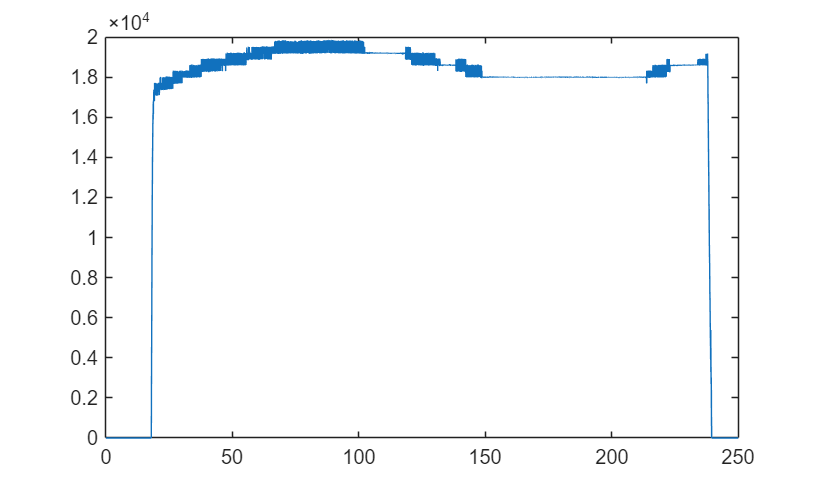

plot(RPMResult_time,RPMResult_Clean)

## Preprocessing - Filter noise + Smooth data

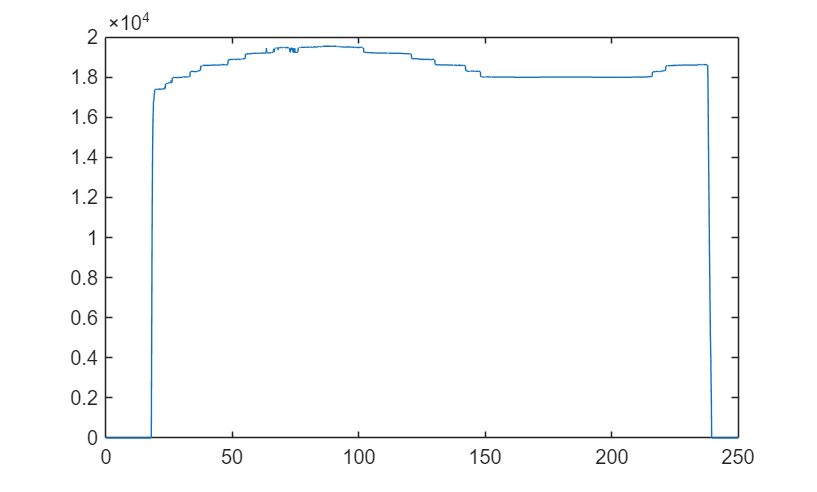

%signalAnalyzer
%RPMResult_Clean_func = baseline_model_Clean(RPMResult_Clean, RPMResult_time);
RPMResult_Clean_func = smoothdata(RPMResult_Clean,'movmedian',1,'SamplePoints',RPMResult_time);
plot(RPMResult_time,RPMResult_Clean_func)

## Preprocessing - Resampling from 1000Hz to 100Hz [Normalize to RPM data 100Hz]

length(PWMRequest)

ans = 250001

length(RPMResult_Clean_func)

ans = 25001

% Resample PWMRequest to 100Hz
PWMRequest_Resam_100Hz = resample(PWMRequest, PWMRequest_time, 100);
length(PWMRequest_Resam_100Hz)

ans = 25001

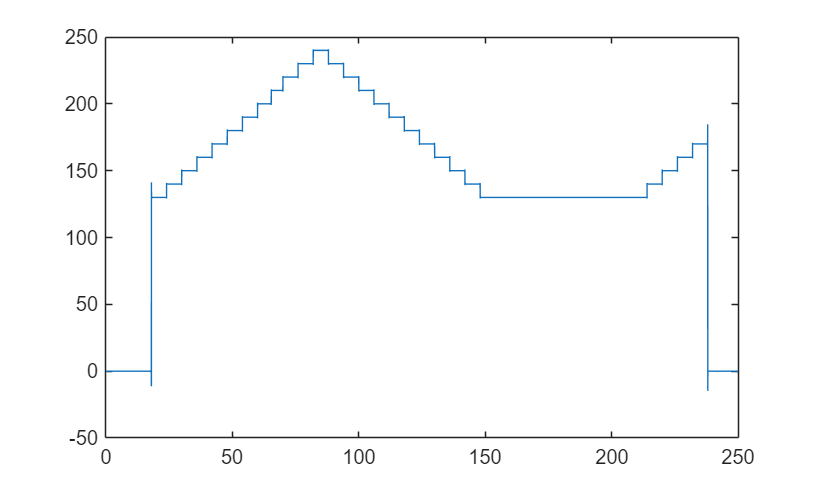

plot(RPMResult_time,PWMRequest_Resam_100Hz)

## Preprocessing - Cleaning outlier

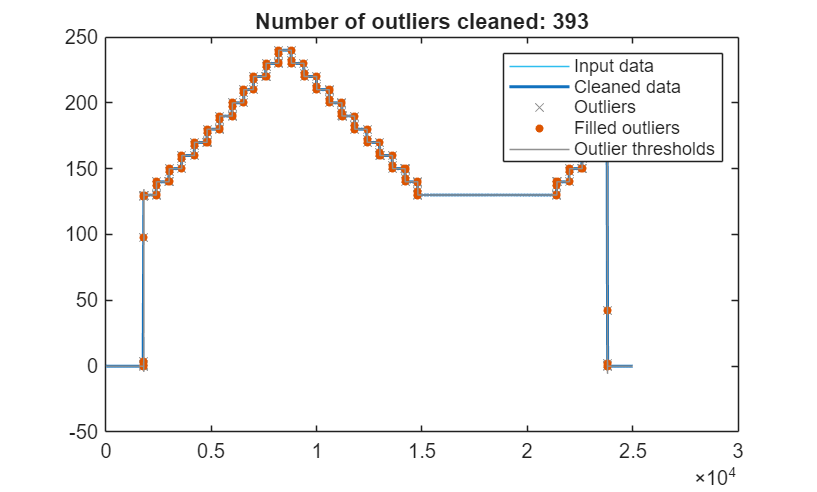

% Fill outliers
[PWMRequest_Resam_100Hz,outlierIndices3,lo2,hi2] = filloutliers(PWMRequest_Resam_100Hz, ...
    "center","movmedian",100,ThresholdFactor=0.5);

% Display results
figure
plot(PWMRequest_Resam_100Hz,SeriesIndex=6,DisplayName="Input data")
hold on
plot(PWMRequest_Resam_100Hz,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")

% Plot outliers
plot(find(outlierIndices3),PWMRequest_Resam_100Hz(outlierIndices3),"x", ...
    Color=[145 145 145]/255,DisplayName="Outliers")

% Plot filled outliers
plot(find(outlierIndices3),PWMRequest_Resam_100Hz(outlierIndices3),".",MarkerSize=12, ...
    SeriesIndex=2,DisplayName="Filled outliers")

% Plot outlier thresholds
plot([(1:numel(PWMRequest_Resam_100Hz))'; missing; (1:numel(PWMRequest_Resam_100Hz))'], ...
    [hi2(:); missing; lo2(:)],Color=[145 145 145]/255, ...
    DisplayName="Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices3))
legend

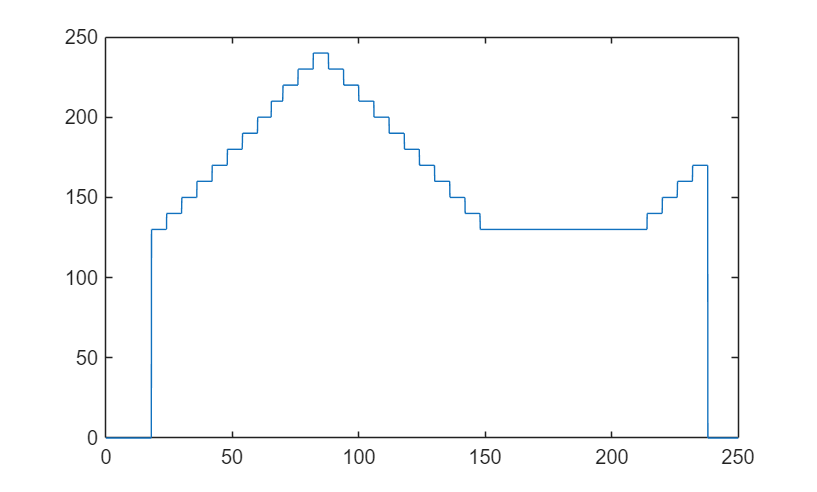

clear lo2 hi2
plot(RPMResult_time,PWMRequest_Resam_100Hz)

## SystemIdentification - Transfer funciton model

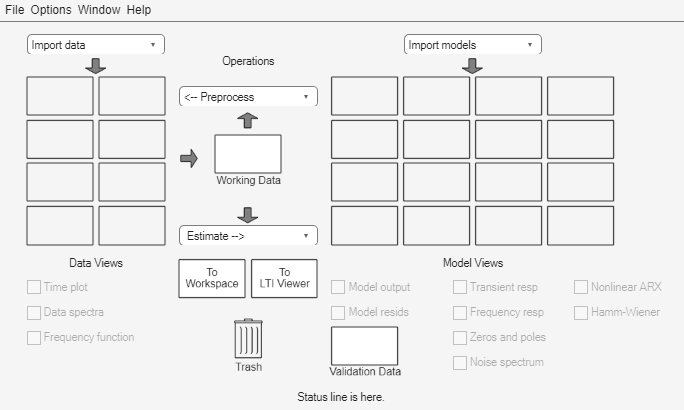

%systemIdentification